clc;
clear;
close all;

% Given information
M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

%Defining system matrices
A=[0 1 0 0 0 0;
    0 0 (-m1*g/M) 0 (-m2*g/M) 0;
    0 0 0 1 0 0;
    0 0 ((-g*(M+m1))/(l1*M)) 0 ((-g*m2)/(l1*M)) 0;
    0 0 0 0 0 1;
    0 0 ((-g*m1)/(l2*M)) 0 ((-g*(M+m2))/(l2*M)) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

C=eye(6);
D=0;

%Defining the output vectors 
x_only = [1 0 0 0 0 0];  
x_theta2 = [1 0 0 0 0 0; 0 0 0 0 1 0]; 
x_theta1_theta2 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; 

% Cosidering the same Q and R matrices chosen before in our code
Q=[10 0 0 0 0 0;
    0 10 0 0 0 0 ;
    0 0 200 0 0 0;
    0 0 0 200 0 0;
    0 0 0 0 200 0;
    0 0 0 0 0 200];

R=0.001; 

%Initial State, here we are considering 6 actual and 6 estimates
x0=[1,0,deg2rad(10),0,deg2rad(20),0,0,0,0,0,0,0];

%Define Poles
poles=[-1;-2;-3;-4;-5;-6];

% Calling LQR function to obtain K matrix
[K,S,P]=lqr(A,B,Q,R);

%Placing the poles 
Luenberger_x_only = place(A',x_only',poles)';
Luenberger_x_theta2 = place(A',x_theta2',poles)';
Luenberger_x_theta1_theta2 = place(A',x_theta1_theta2',poles)';

%
B_d = [B;zeros(size(B))];

%System one x(t)
A_x_only = [(A-B*K) B*K; zeros(size(A-B*K)) (A-Luenberger_x_only*x_only)];

C_x_only = [x_only zeros(size(x_only))];% Luenberger C matrix

system_x_only = ss(A_x_only, B_d, C_x_only,D);
disp('Response for X(t) output vector system')

Response for X(t) output vector system


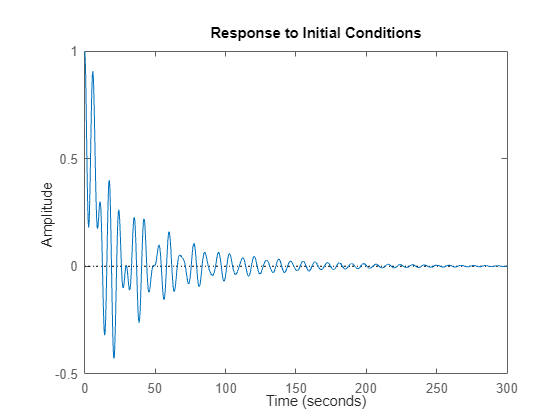

figure 
initial(system_x_only,x0)

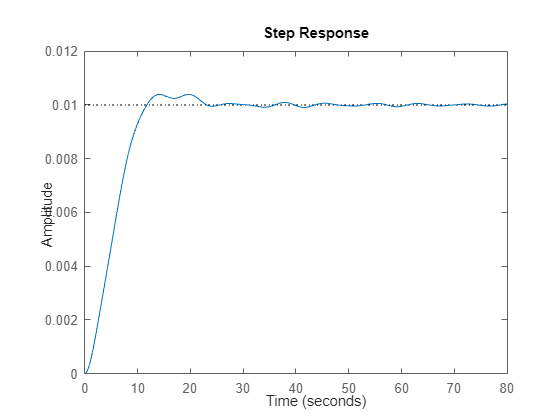

figure
step(system_x_only)




%System X(t) and theta2(t)
A_x_theta2=[(A-B*K) B*K;
        zeros(size(A)) (A-Luenberger_x_theta2*x_theta2)];

C_x_theta2 = [x_theta2 zeros(size(x_theta2))];% Luenberger C matrix

system_x_theta2 = ss(A_x_theta2, B_d, C_x_theta2,D);
disp('Response for X(t),theta_1(t) output vector system')

Response for X(t),theta_1(t) output vector system


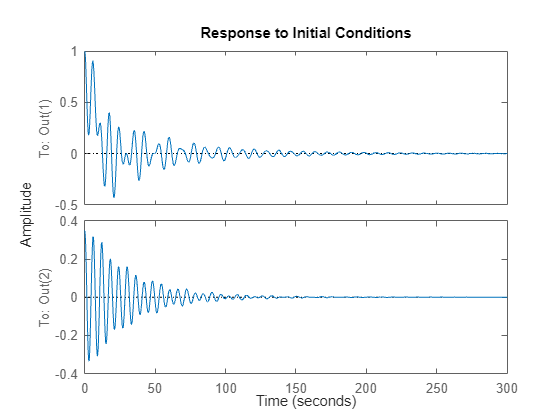

figure 
initial(system_x_theta2,x0)

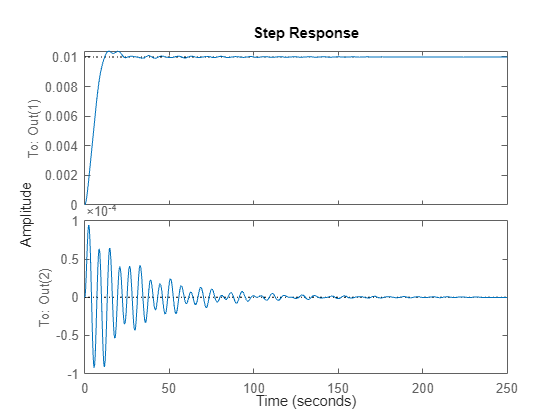

figure
step(system_x_theta2)


%System x(t), theta1(t) and theta2(t)
A_x_theta1_theta2 = [(A-B*K) B*K; 
        zeros(size(A)) (A-Luenberger_x_theta1_theta2*x_theta1_theta2)];
B_d = [B;zeros(size(B))];
C_x_theta1_theta2 = [x_theta1_theta2 zeros(size(x_theta1_theta2))];

system_x_theta1_theta2 = ss(A_x_theta1_theta2, B_d, C_x_theta1_theta2,D);
disp('Response for X(t),theta_1(t) and theta_2(t) output vector system')

Response for X(t),theta_1(t) and theta_2(t) output vector system


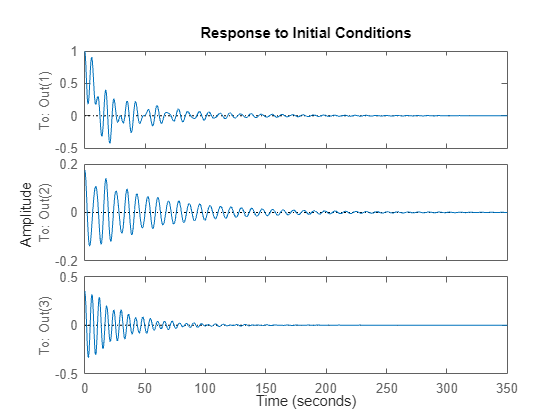

figure
initial(system_x_theta1_theta2,x0)

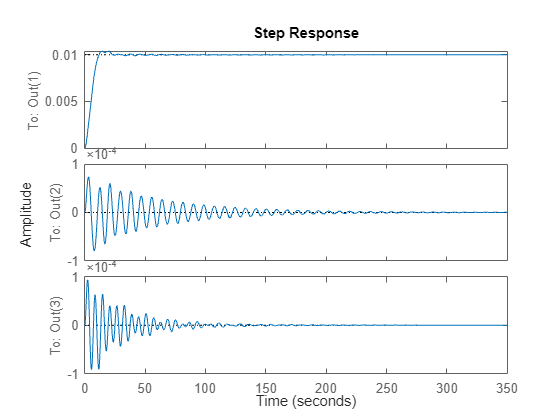

step(system_x_theta1_theta2)